# Horizontal Wave Number Spectrum

### Define parameters: latitude, stratification, local depth

%Stratification
N0 = 3*2*pi/3600;
L_gm = 1300;
N2Func = @(z) N0*N0*exp(2*z/L_gm);
latitude=33;

%Depth
Lz=4000;       


### Initialize the function

im = InternalGravityWaveSpectrum(N2Func,Lz,nModes=64);

### Initializing Wave-Vortex Model for comparisons

One VERY important thing is to run the model and the toolbox in similar scales.

**Horizontal:** I asked the toolbox to create waves with the horizontal scales between

100km and 1km. At same time I run the WVM with a 100km domain and a 782 m dx.

**Vertical: **I run the toolbox and the model with the same depth and same number of vertical mode. 

%%%% DOMAIN
N = 64;
aspectRatio = 1;

Lx = 100e3;
Ly = aspectRatio*100e3;

Nx = N;
Ny = aspectRatio*N;
Nz = 128+1; % 2^n + 1 grid points, to match the Winters model, but 2^n ok too.

wvt = WVTransformBoussinesq([Lx, Ly, Lz], [Nx, Ny, Nz], latitude=latitude, N2=N2Func);

The operation nonlinearFlux with variables {Fp,Fm,F0,} has been removed and the operation WVNonlinearFlux with variables {Fp,Fm,F0,} has been added.


wvt.initWithAlternativeSpectrum;

### Get the complex velocity from WVModel in function of K-band and vertical mode, j.

%FMatrix and GMatrix are hydrostatic [Nj,Nz]
% Ap Am [Nj,Nkl]
u_jk = wvt.UAp .* wvt.Ap + wvt.UAm .* wvt.Am;
v_jk = wvt.VAp .* wvt.Ap + wvt.VAm .* wvt.Am;
u_klz = zeros([wvt.Nz wvt.Nkl]);
v_klz = zeros([wvt.Nz wvt.Nkl]);
%Loop over K to get the non-hydrostatics
for iK=1:length(wvt.K2unique)
    indices = wvt.K2uniqueK2Map{iK};
    %pre-conditining matrix Ppm
    u_klz(:,indices) = wvt.PFpmInv(:,:,iK )*(wvt.Ppm(:,iK) .* u_jk(:,indices));
    v_klz(:,indices) = wvt.PFpmInv(:,:,iK )*(wvt.Ppm(:,iK) .* v_jk(:,indices));
end

%get u2 and v2 BEFORE summing
u2_klz = u_klz .* conj(u_klz);
v2_klz = v_klz .* conj(v_klz);

u2_Kz=zeros(wvt.Nj,length(wvt.kRadial));
v2_Kz=zeros(wvt.Nj,length(wvt.kRadial));

kRadial = wvt.kRadial;
Kh = wvt.Kh(1,:);
dk = kRadial(2)-kRadial(1);

for iK=1:length(kRadial)
    for indz=1:length(wvt.z)
        indicesForK = kRadial(iK)-dk/2 < Kh & Kh <= kRadial(iK)+dk/2;
        % Factor 2 here accounts for the hermitian conjugate!
        u2_Kz(indz,iK)= 2*sum(u2_klz(indz,indicesForK));
        v2_Kz(indz,iK)= 2*sum(v2_klz(indz,indicesForK));
    end
end

Check that the variance matches at each depth. The factor of 2 is because the WVT discards the hermitian conjugate.

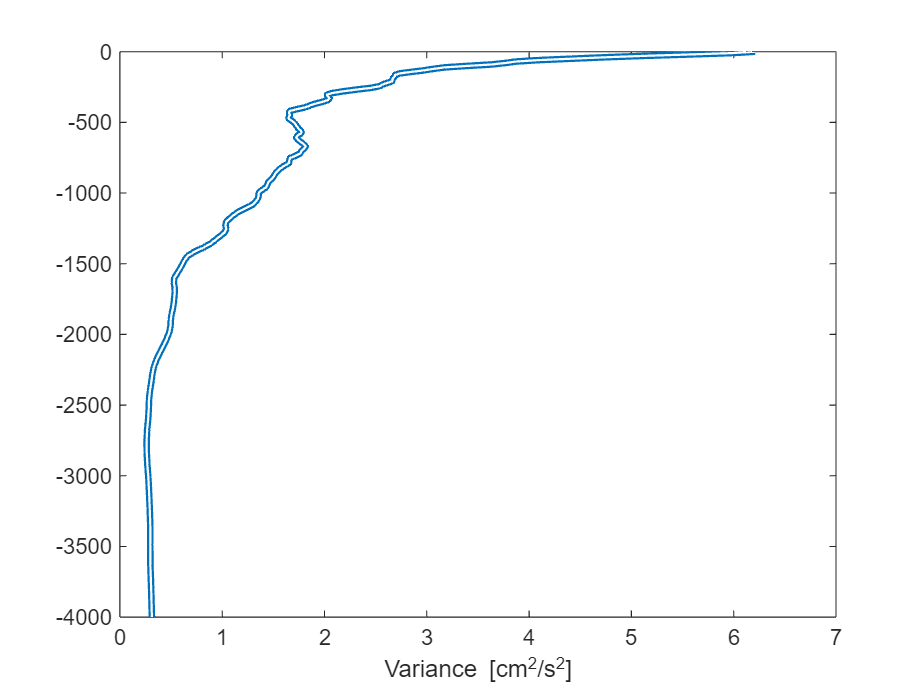

clf
plot(1000*(sum(u2_Kz,2)+sum(v2_Kz,2)),wvt.z, LineWidth=3), hold on
plot(1000*squeeze(mean(mean(wvt.u.^2 + wvt.v.^2,1),2)),wvt.z,LineWidth=1.0,Color=1*[1 1 1])
xlabel("Variance [cm^2/s^2]")

Interping for a specific depth

z=-200;
wvtHKE =((1/2)*(u2_Kz + v2_Kz));
wvtHKEatZ=interp1(wvt.z,wvtHKE,z); 


## Plotting

% In the toolbox I'm integrating over dk that are not
% equally spaced in linear space, as it is on WVM...
% L2 in WVM is hydrostatic and in the toolbox it
% is non-hydrostaic.
% I should compute the hydrostatic L2 for my function 
% on the WVM!
dkWVT=wvt.kRadial(2)-wvt.kRadial(1);

clf

HKEAtHorizontalWavenumber = im.energyAtHorizontalWavenumber(z,'HKE',plot=0);

Arrays have incompatible sizes for this operation.

Error in InternalGravityWaveSpectrum/energyAtHorizontalWavenumber (line 389)
            HKEatk=HKEatk./self.dKLog;

Related documentation

loglog(im.KRadialLog,HKEAtHorizontalWavenumber*1000)
hold on
loglog(wvt.kRadial,wvtHKEatZ*1000/dkWVT)
set(gca,'xscale','log')
title('Power spectrum density')
%ylabel('Energy')
xlabel('Horizontal Wave Number')
legend('Toolbox','WVModel')